# Assessment 4

The task given is about predicting a time series.

To adapt my algorithm for this task I had to do two things: 

- Adapt the RNNet function to add the BIAS to the activation array

- Assign fitness values that increase the better the node gets.

The first point was trivial, to achieve the second I assigned a fitness value of 1000 - the achieved rmse of the evaluation.

I chose a topology of 1,3,1 - just guessing.

The first figure of the report shows the fitness progression of the best net per generation. This one should not be in the report, but I forgot to disable this output while running may esp algorithm.

clear;

## Initialize parameters

load('cycling1.mat');
parameters.topology = [1,10,1];
parameters.permutationOption = 1; % Random Grouping
parameters.elitismOption = 2; % Node Elitism
parameters.maximumGenerations = 200;
parameters.targetFitness = 1000 - (1e-3);
load('cycling1.mat');
parameters.tdata = tdata(1:3);

## Running ESP

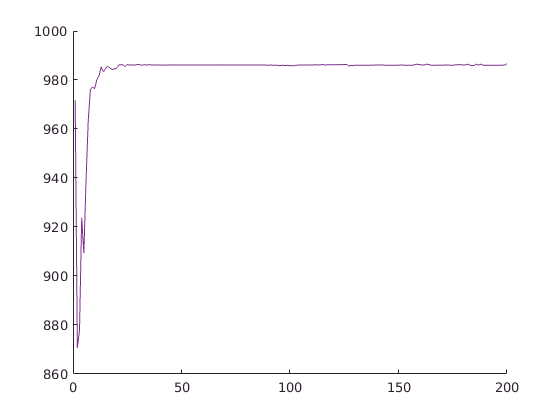

r = doEsp( parameters);

save r 'r';

## Run best found network on training data

[rmse,predictions,targets,inputs] = heartrate(r.bestNetwork, @RNNet, tdata(1:3));

## Vizualization

This plots the first time series 

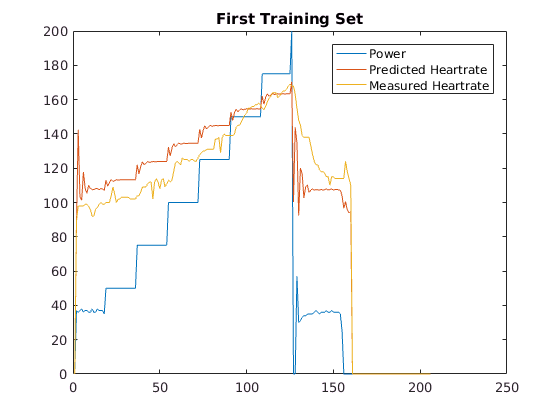

figure(2);
plot(inputs(1,:));hold on;
plot(predictions(1,:));
plot(targets(1,:));
legend('Power','Predicted Heartrate', 'Measured Heartrate');
title('First Training Set');
hold off;

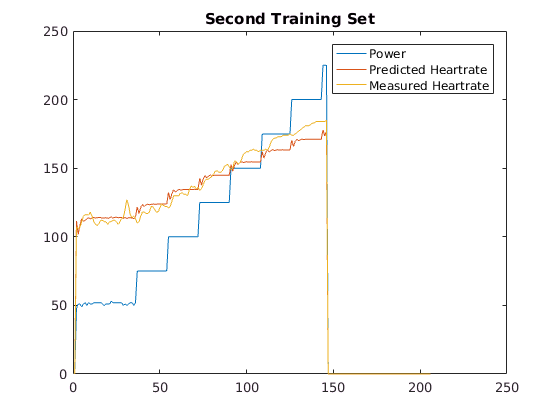


figure(3);
plot(inputs(2,:));hold on;
plot(predictions(2,:));
plot(targets(2,:));
legend('Power','Predicted Heartrate', 'Measured Heartrate');
title('Second Training Set');
hold off;

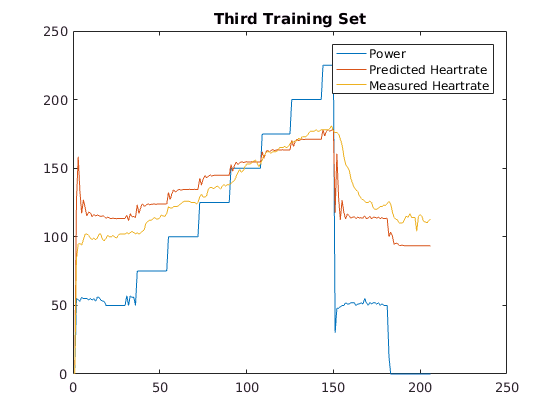


figure(4);
plot(inputs(3,:));hold on;
plot(predictions(3,:));
plot(targets(3,:));
legend('Power','Predicted Heartrate', 'Measured Heartrate');
title('Third Training Set');
hold off;

## Run best found network on Test Set

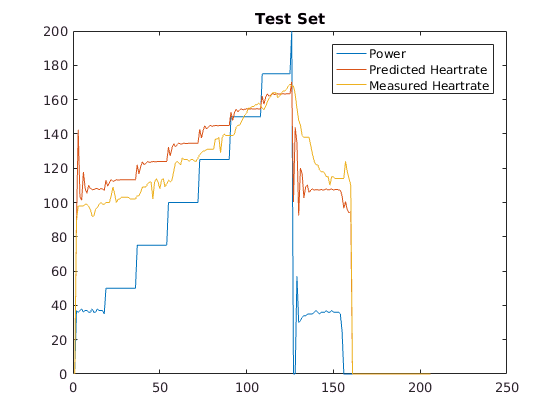

[rmse,predictions,targets,inputs] = heartrate(r.bestNetwork, @RNNet, tdata(1:3));

figure(5);
plot(inputs(1,:));hold on;
plot(predictions(1,:));
plot(targets(1,:));
legend('Power','Predicted Heartrate', 'Measured Heartrate');
title('Test Set');
hold off;

## Results

For training set two the predictions look quite accurate, for the rest - including the test set - the predictions do look okay as well. One can see that some generalization took place. Increasing the number of neurons could possibly lead to better fit with the danger of overfitting.